%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

引用了不存在的字段 'start'。

%   Tag:           temp for test method                                                         %
%   Filename:      example.m                                              %
%   Author:        Mingcheng Gu                                           %
%   Created:       August 23, 2024                                        %
%   Version:       1.0                                                    %
%   MATLAB Version: R2019a                                                %
%                                                                         %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                                                                         %
%   Revision History:                                                     %
%   Version 1.0 - Initial version (August 23, 2024)                       %
%                                                                         %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

path = uigetdir;
if(isempty(path)) 
    return;
end

% file acquisition

fileList   = dir(path);
matFiles   = dir(fullfile(path, '*.mat'));
paramFiles = dir(fullfile(path, '*.txt'));

bpFilePath    = tempFindPathOfdata(matFiles, "mat");
paramFilePath = tempFindPathOfdata(paramFiles, "txt");

mergedInfo = tempMatchPathOfBpAndParams(bpFilePath, paramFilePath);

OneExperimentData = tempReadData(mergedInfo); 

% statistical calculations\
% First seek stimulation segment
%---------------------------------------------------------------------------
taiChongData = OneExperimentData.TaiChong3;

% acquire the same length data of BP and syncSingal
readLength = min(taiChongData.Data3__Stopped__Ch1.length, taiChonga);
taiChongdataBP = taiChongData.Data3__Stopped__Ch1.values(1: readLength);
taiChongdataStimu = taiChongData.Data3__Stopped__Ch2.values(1: readLength);

% acquire sync information, which contains the duration of stimulation
taiChongdataStimuSmooth = tempSmoothSnycWave(taiChongdataStimu); % 这里复杂了，其实可以重写到taiChongStimu
syncInfo = tempConfirmSyncSegment(taiChongdataStimuSmooth);

% match segment and parameter

if(length(taiChongData.params) ~= length(syncInfo))
    error("The length of parameter record is not match the number of trigger");
end

for I = 1:size(syncInfo, 1)
    taiChongData.params(I).start = syncInfo(I, 1);
    taiChongData.params(I).end = syncInfo(I,2);
end
%-------------------------------------------------------------------------
% 以上的内容需要放入到类中进行，最后获得数据是struct， 包含每个位置的刺激数据

% Splite the stimulation segment, before stimulus, after stimulus
intervals = tempSplitInterval(taiChongData.params);

% this should be aquires from the OneExperimentData;
acupuncutureName = "taiChong";
ExperimentDate = "20240606";

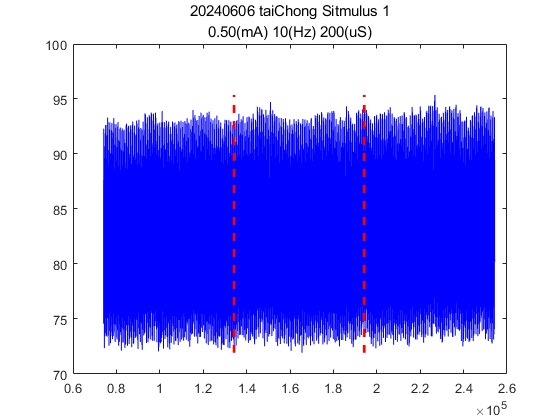

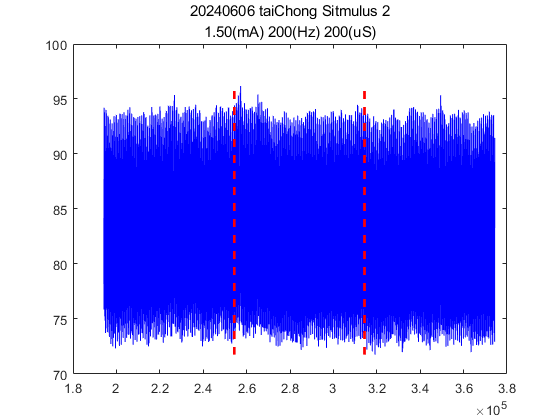

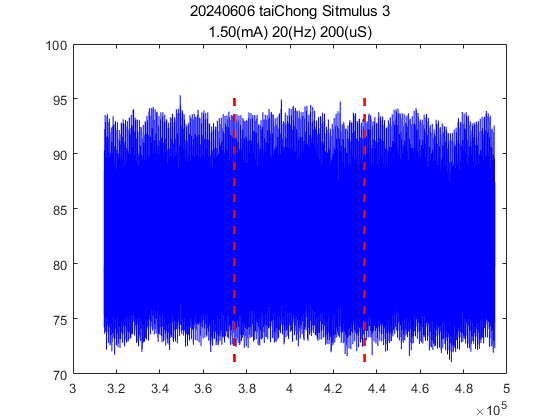

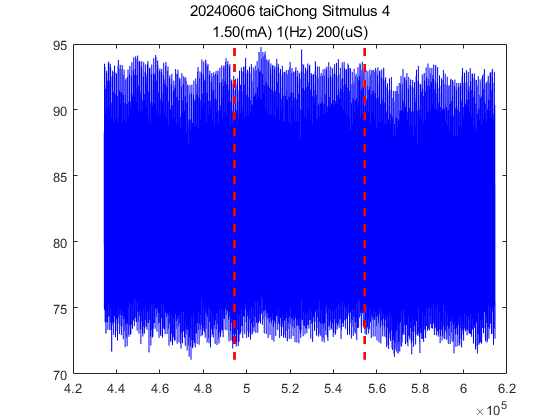

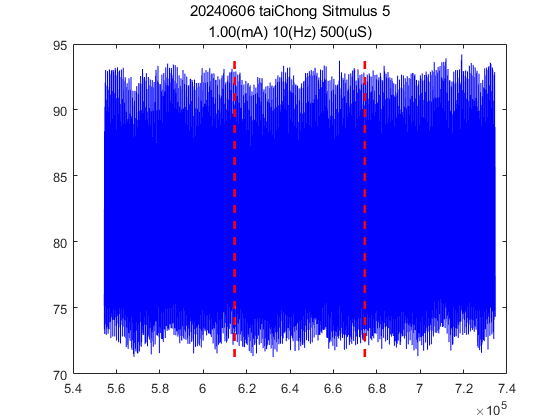

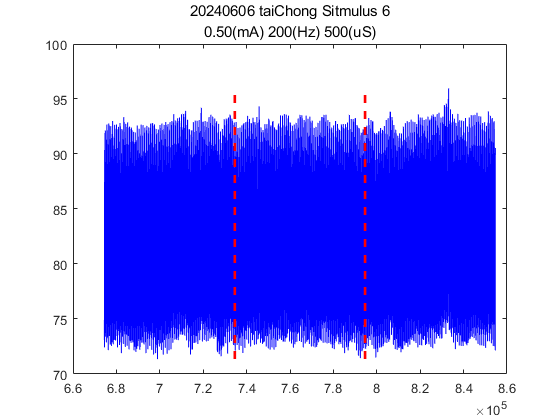

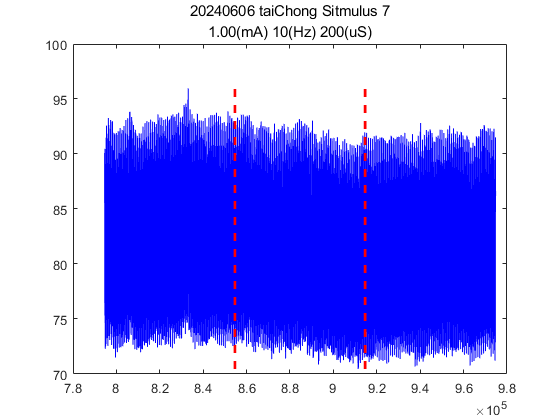

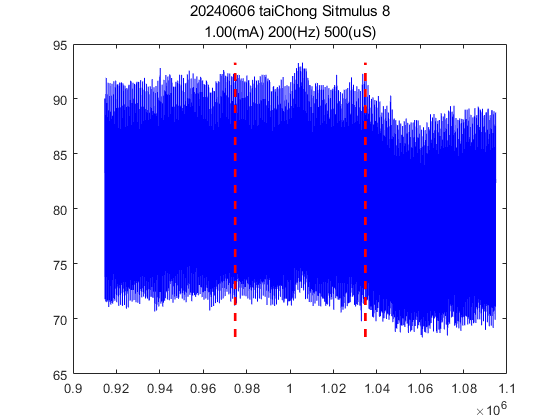

savePath = uigetdir;
tempSplitDataSegment(taiChongdataBP, acupuncutureName, ExperimentDate, taiChongParamter, intervals, savePath);